# Exercise 2: Data preparation for use with AI models

In this exercise, you will prepare a training dataset so that it can be effectively utilized by machine learning algorithms. You will import raw data, explore and visualize it to gain insights, and then preprocess it to ensure it's in the optimal format for model training. This preparation is crucial for enhancing the performance and accuracy of AI models.

## Task 0: Load the data

Before you begin the actual tasks for data preparation, you should load the product data in this folder stored in the *product_data.csv* file. If the data is not loaded, you might see errors in the subsequent tasks.

 products_data = readtable('products_data.csv', 'VariableNamingRule', 'preserve');

## Task 1: Import the data

Description:

- This task involves importing the dataset into the MATLAB workspace. The Import Data Live Task provides options to customize the import process, such as specifying data types and handling missing values.

- For this exercise, importing the data as a table is ideal, as it allows for easy manipulation and analysis.

Instructions:

- Click the "Browse" button in the Import Data Live Task below.

- Choose the `Products_Data.csv` file and click the "Open" button.

Expected Results:

- The `Products_Data.csv` file is successfully imported into the MATLAB workspace as a table.

- The live task displays the imported data, showing a preview of the table and allowing you to verify the import process.

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Name", "Ingredients", "Category"];
opts.VariableTypes = ["double", "string", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Ingredients", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Ingredients", "Category"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Name", "TrimNonNumeric", true);
opts = setvaropts(opts, "Name", "ThousandsSeparator", ",");

% Import the data
products_data = readtable("/MATLAB Drive/Repositories/beyond-the-label/Exercise2_DataPreprocessingAndVisualization/products_data.csv", opts);

% Clear temporary variables
clear opts

% Display results
products_data

products_data = 500x3 table
    Name                                                                                                                                                                                                                  Ingredients                                                                                                                                                                                                                  Category
    ____    _______________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________    

## Task 2: Explore and Visualize Data

Description:

- This task involves exploring the dataset to understand its structure and contents. The `summary` command provides an overview of the dataset's properties, such as variable types and basic statistics.

- Visualizing data using histograms helps you examine the distribution of categorical variables, such as "Category," by organizing data into bins.

Instructions:

- Using the "Run Section" button located on the "Live Editor" tab of the toolstrip above, run the provided code.

Expected Results:

- The `summary` command outputs the properties and statistics of the dataset, such as the number of entries, data types, and any missing values.

- Histograms for the "Category" variables are displayed, allowing you to observe their distribution and identify any patterns or imbalances in the data.

summary(products_data)


products_data: 500x3 table

Variables:

    Name: double
    Ingredients: string
    Category: categorical (2 categories)

Statistics for applicable variables:

                   NumMissing     Min        Median         Max          Mean            Std     

    Name               0           1        250.5000        500        250.5000        144.4818  
    Ingredients        0                                                                         
    Category           0                                                                         



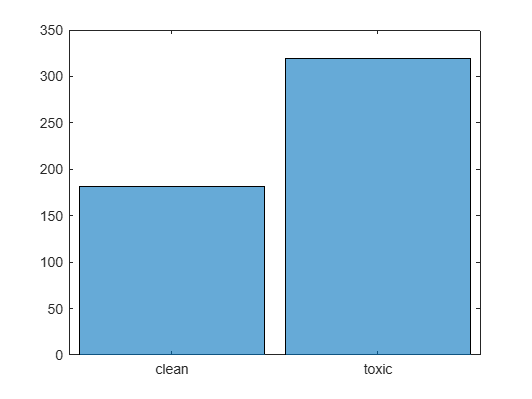

h2 =   Histogram with properties:

              Data: [500x1 categorical]
            Values: [181 319]
    NumDisplayBins: 2
        Categories: {'clean'  'toxic'}
      DisplayOrder: 'data'
     Normalization: 'count'
      DisplayStyle: 'bar'
         FaceColor: 'auto'
         EdgeColor: [0 0 0]

  Show all properties


h2 = histogram(products_data.Category)

## Task 3: Pre-process the data

Description:

- This task focuses on preprocessing the text data to prepare it for machine learning. Tokenization breaks text into individual words or tokens, stop words are removed to reduce noise, and case normalization ensures uniformity by converting text to lowercase.

- A word cloud visually represents the most frequent words in the dataset, providing insights into common terms and themes.

Instructions:

- Select data by setting Data to products_data from the dropdown. If you do not see products_data, run Task 0 again.

- Tokenize the data, remove stop words, and perform case normalization.

- Display a word cloud using the live task for preprocessing data.

Expected Results:

- The text data is successfully tokenized, cleaned of stop words, and normalized in terms of case.

- A word cloud is generated, visually highlighting the most common words in the dataset. This helps identify key terms that may influence the model's predictions.

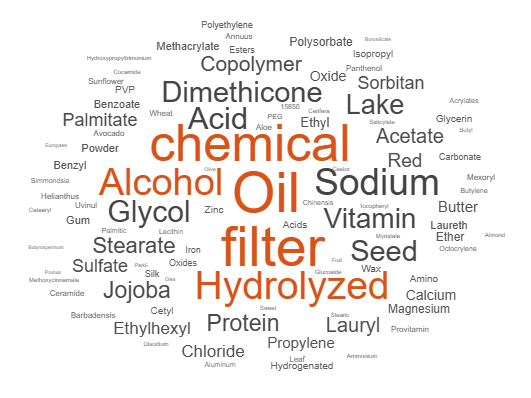

%% Preprocess Text
preprocessedText = products_data.Ingredients;

% Tokenize
preprocessedText = tokenizedDocument(preprocessedText);

% Add token details
preprocessedText = addPartOfSpeechDetails(preprocessedText);

% Change and remove words
preprocessedText = removeShortWords(preprocessedText,2);
preprocessedText = removeLongWords(preprocessedText,51);
preprocessedText = removeStopWords(preprocessedText,IgnoreCase=true);
preprocessedText = erasePunctuation(preprocessedText);

% Display results
wordcloud(preprocessedText);